clc; clear; close all;
rng(42); % Semilla para reproducibilidad
load('digits.mat');
[num_pixels, num_samples] = size(digits.image); % 784 x 10000

fprintf('\n--- Comparación progresiva de LDA con subclases crecientes ---\n');


--- Comparación progresiva de LDA con subclases crecientes ---



X = digits.image';
Y = digits.label;

num_digits = 10;
min_subclasses = 1;
max_subclasses_target = 4;
step = 1; % Aumentar 2 subclases por vez

% Inicialización de tracking de precisión
num_steps = ceil((max_subclasses_target - min_subclasses) / step) * num_digits + 1;
accuracy_knn_all = zeros(num_steps, 1);
accuracy_bayes_all = zeros(num_steps, 1);
digit_accuracy_knn = zeros(num_steps, 1);
digit_accuracy_bayes = zeros(num_steps, 1);
digit_modified = zeros(num_steps, 1);

% Inicialización de número de subclases por dígito
N_subclasses = ones(1, num_digits);

step_idx = 1;

while any(N_subclasses < max_subclasses_target)
    fprintf("Paso %d - Subclases: [%s]\n", step_idx, num2str(N_subclasses));

    X_clustered = [];
    Y_clustered = [];
    original_labels = [];

    for d = 0:9
        idx = find(Y == d);
        X_digit = X(idx, :);
        n_sub = N_subclasses(d + 1);

        [sub_idx, ~] = kmeans(X_digit, n_sub, 'Replicates', 3);

        for j = 1:n_sub
            sub_mask = (sub_idx == j);
            X_sub = X_digit(sub_mask, :);

            new_label = d * max_subclasses_target + j;

            X_clustered = [X_clustered; X_sub];
            Y_clustered = [Y_clustered; repmat(new_label, sum(sub_mask), 1)];
            original_labels = [original_labels; repmat(d, sum(sub_mask), 1)];
        end
    end

    % LDA
    lda_model = fitcdiscr(X_clustered, Y_clustered, 'DiscrimType', 'pseudoLinear');
    class_means = lda_model.Mu';
    X_centered = X_clustered - mean(X_clustered);
    [U, ~, ~] = svd(class_means - mean(class_means, 2), 'econ');

    num_subclasses_total = numel(unique(Y_clustered));
    W_proj = U(:, 1:(num_subclasses_total - 1));
    X_lda = X_centered * W_proj;

    % División train/test
    num_samples = size(X_lda, 1);
    num_train = round(0.9 * num_samples);
    idx_all = randperm(num_samples);
    train_idx = idx_all(1:num_train);
    test_idx = idx_all(num_train+1:end);

    X_train = X_lda(train_idx, :);
    X_test = X_lda(test_idx, :);
    Y_train = original_labels(train_idx);
    Y_test = original_labels(test_idx);

    % KNN
    knn_model = fitcknn(X_train, Y_train, 'NumNeighbors', 3);
    Y_pred_knn = predict(knn_model, X_test);
    accuracy_knn_all(step_idx) = mean(Y_pred_knn == Y_test);

    % Bayes
    bayes_model = fitcnb(X_train, Y_train);
    Y_pred_bayes = predict(bayes_model, X_test);
    accuracy_bayes_all(step_idx) = mean(Y_pred_bayes == Y_test);

    % Guardar precisión específica del dígito modificado
    d_mod = mod(step_idx - 1, num_digits); % dígito modificado en este paso
    idx_digit = (Y_test == d_mod);
    digit_accuracy_knn(step_idx) = mean(Y_pred_knn(idx_digit) == d_mod);
    digit_accuracy_bayes(step_idx) = mean(Y_pred_bayes(idx_digit) == d_mod);
    digit_modified(step_idx) = d_mod;

    % Incrementar subclases del siguiente dígito (si aún no llegó al máximo)
    for d = 0:9
        if N_subclasses(d + 1) < max_subclasses_target
            N_subclasses(d + 1) = N_subclasses(d + 1) + step;
            break;
        end
    end

    step_idx = step_idx + 1;
end

Paso 1 - Subclases: [1  1  1  1  1  1  1  1  1  1]
Paso 2 - Subclases: [2  1  1  1  1  1  1  1  1  1]
Paso 3 - Subclases: [3  1  1  1  1  1  1  1  1  1]
Paso 4 - Subclases: [4  1  1  1  1  1  1  1  1  1]
Paso 5 - Subclases: [4  2  1  1  1  1  1  1  1  1]
Paso 6 - Subclases: [4  3  1  1  1  1  1  1  1  1]
Paso 7 - Subclases: [4  4  1  1  1  1  1  1  1  1]
Paso 8 - Subclases: [4  4  2  1  1  1  1  1  1  1]
Paso 9 - Subclases: [4  4  3  1  1  1  1  1  1  1]
Paso 10 - Subclases: [4  4  4  1  1  1  1  1  1  1]
Paso 11 - Subclases: [4  4  4  2  1  1  1  1  1  1]
Paso 12 - Subclases: [4  4  4  3  1  1  1  1  1  1]
Paso 13 - Subclases: [4  4  4  4  1  1  1  1  1  1]
Paso 14 - Subclases: [4  4  4  4  2  1  1  1  1  1]
Paso 15 - Subclases: [4  4  4  4  3  1  1  1  1  1]
Paso 16 - Subclases: [4  4  4  4  4  1  1  1  1  1]
Paso 17 - Subclases: [4  4  4  4  4  2  1  1  1  1]
Paso 18 - Subclases: [4  4  4  4  4  3  1  1  1  1]
Paso 19 - Subclases: [4  4  4  4  4  4  1  1  1  1]
Paso 20 - Subclases: 

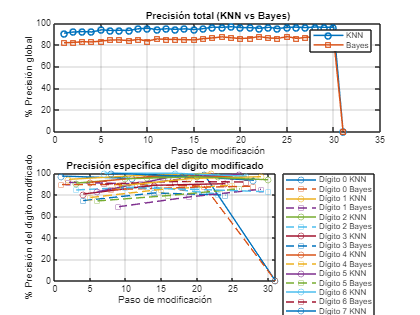


% === GRAFICAR ===

figure;
subplot(2, 1, 1);
plot(1:num_steps, accuracy_knn_all*100, '-o', 'LineWidth', 1.5);
hold on;
plot(1:num_steps, accuracy_bayes_all*100, '-s', 'LineWidth', 1.5);
xlabel('Paso de modificación');
ylabel('% Precisión global');
title('Precisión total (KNN vs Bayes)');
legend('KNN', 'Bayes');
grid on;

subplot(2, 1, 2);
for d = 0:9
    idx = (digit_modified == d);
    if any(idx)
        plot(find(idx), digit_accuracy_knn(idx)*100, '-o', 'DisplayName', ['Dígito ', num2str(d), ' KNN']);
        hold on;
        plot(find(idx), digit_accuracy_bayes(idx)*100, '--s', 'DisplayName', ['Dígito ', num2str(d), ' Bayes']);
    end
end
xlabel('Paso de modificación');
ylabel('% Precisión del dígito modificado');
title('Precisión específica del dígito modificado');
legend('Location', 'bestoutside');
grid on;